# **Matlab案例代码解析**

## 5. 智能优化算法案例

### 5.9 蜣螂（**DBO**）

#### 5.8.1 **DBO**求解函数极值

算法下载：[https://ww2.mathworks.cn/matlabcentral/fileexchange/121318-dung-beetle-optimizer-a-new-meta-heuristic-algorithm?s_tid=srchtitle_Dung%2520Beetle%2520Optimizer_3](https://ww2.mathworks.cn/matlabcentral/fileexchange/121318-dung-beetle-optimizer-a-new-meta-heuristic-algorithm?s_tid=srchtitle_Dung%2520Beetle%2520Optimizer_3)

clear;clc;
% 鲸鱼数量
SearchAgents_no = 30;
% 最大迭代次数
Max_iter = 200;
% 变量维度
dim = 2;
% 上限
ub = 10 * ones(1, dim);
% 下限
lb = -10 * ones(1, dim);
% 生产者
P_percent = 0.2;
pNum = round(SearchAgents_no *  P_percent); 
%%%%% 初始化
Convergence_curve = zeros(1, Max_iter);
% 初始值
x = zeros(SearchAgents_no, dim);
fit = zeros(1, SearchAgents_no);
for i = 1 : SearchAgents_no
    x(i, :) = lb + (ub - lb) .* rand(1, dim);
    fit(i) = ObjFun(x(i, :));
end

pFit = fit;
pX = x;
XX = pX;
% 全局最优
[fMin, bestI] = min(fit);
bestX = x(bestI, :);

% Start updating the solutions
for t = 1 : Max_iter
    [fmax, B] = max(fit);
    worse = x(B, :);
    r2 = rand(1);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for i = 1 : pNum
        if(r2 < 0.9)
            r1 = rand(1);
            a = rand(1);
            if (a > 0.1)
                a = 1;
            else
                a = -1;
            end
            % 公式（1）
            x(i, :) = pX(i, :) + 0.3*abs(pX(i, :) - worse) + a*0.1*(XX(i, :)); 
        else
            
            aaa = randperm(180, 1);
            if (aaa == 0 || aaa == 90 || aaa == 180 )
                x(i, :) = pX(i, :);
            end
            theta = aaa*pi/180;
            % 公式（2）
            x(i, :) = pX(i, :) + tan(theta).*abs(pX(i, :) - XX(i, :));
            
        end
        % 边界吸收
        x(i, :) = Bounds(x(i, :), lb, ub);
        fit(i) = ObjFun(x(i, :));
    end
    % 当前最优值
    [fMMin, bestII] = min(fit);  
    bestXX = x(bestII, :);
    
    R = 1 - t/Max_iter;
    % 公式（3）
    Xnew1 = bestXX .* (1 - R);
    Xnew2 = bestXX .* (1 + R);           
    Xnew1 = Bounds(Xnew1, lb, ub);
    Xnew2 = Bounds(Xnew2, lb, ub);
    % 公式（5） 
    Xnew11 = bestX .* (1 - R);
    Xnew22 = bestX .* (1 + R);              
    Xnew11 = Bounds(Xnew11, lb, ub);
    Xnew22 = Bounds(Xnew22, lb, ub);

    % 公式（4）
    for i = (pNum + 1) : 12 
        x(i, :) = bestXX + ((rand(1, dim)) .* (pX(i, :) - Xnew1) + (rand(1, dim)) .* (pX(i, :) - Xnew2));
        x(i, :) = Bounds(x(i, : ), Xnew1, Xnew2);
        fit(i) = ObjFun(x(i,:)) ;
    end
    
    % 公式（6）
    for i = 13: 19
        x(i, :) = pX(i, :) + ((randn(1)).*(pX(i, :) - Xnew11) + ((rand(1, dim)) .* (pX(i, :) - Xnew22)));
        x(i, :) = Bounds(x(i, :), lb, ub);
        fit(i) = ObjFun(x(i, :)) ;
        
    end
    
    % 公式（7）
    for j = 20 : SearchAgents_no
        x(j, :) = bestX + randn(1, dim) .* ((abs(( pX(j, :) - bestXX))) + (abs((pX(j, :) - bestX))))./2;
        x(j, :) = Bounds(x(j, : ), lb, ub);
        fit(j) = ObjFun(x(j, :)) ;
    end
    
    % 更新个体最优和全局最优
    XX = pX;
    for i = 1 : SearchAgents_no
        if (fit(i) < pFit(i))
            pFit(i) = fit(i);
            pX(i, :) = x(i, :);
        end
        
        if(pFit(i) < fMin)
            fMin = pFit(i);
            bestX = pX(i, :);
        end
    end
    % 收敛曲线
    Convergence_curve(t)=fMin;
end
% 绘图
disp(['最优值：' num2str(bestX)]);

最优值：5.8845e-11  4.4429e-09


disp(['最优值对应目标函数：' num2str(fMin)]);

最优值对应目标函数：0


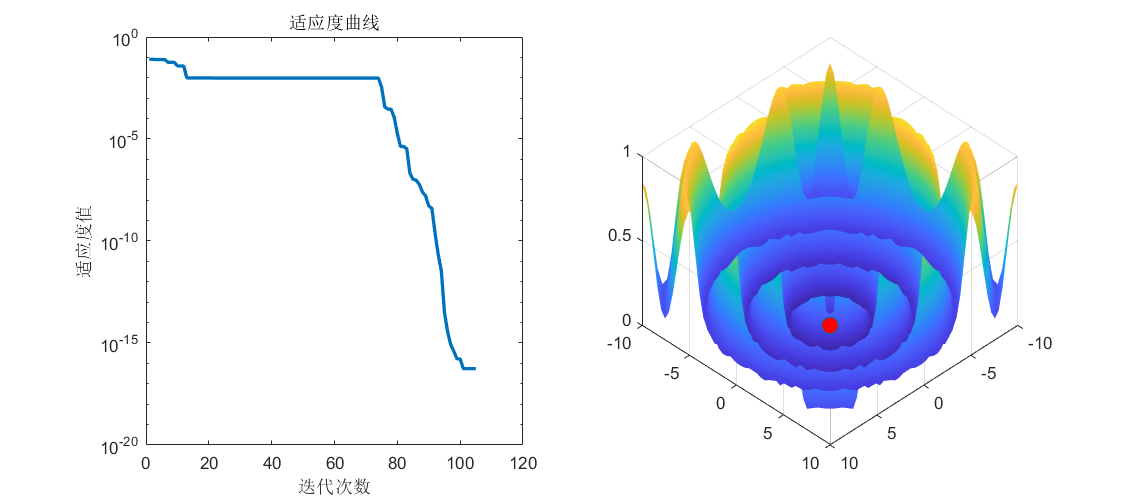

subplot(1, 2, 1)
semilogy(Convergence_curve, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度曲线');
len = 50;
xRange = linspace(lb(1), ub(1), len);
yRange = linspace(lb(2), ub(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(bestX(1), bestX(2), fMin, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end

% 边界吸收
function s = Bounds( s, Lb, Ub)
  temp = s;
  I = temp < Lb;
  temp(I) = Lb(I);
  
  J = temp > Ub;
  temp(J) = Ub(J);
  
  s = temp;
end